%% QPSK Modulation with Rayleigh Noise Addition and Removal in Audio
% This script performs QPSK modulation on audio, adds Rayleigh noise, and
% filters it using a low-pass filter

%% Load the Original Audio File
[audioIn, fs] = audioread('input_voice.wav');  % fs is the sampling rate
audioIn = audioIn(:, 1);  % Use only one channel if stereo
audioIn = audioIn / max(abs(audioIn));  % Normalize input

disp('Playing Original Audio...');

Playing Original Audio...


sound(audioIn, fs);
pause(length(audioIn)/fs + 1);

%% QPSK Modulation
% Convert audio to bits
scaledSignal = uint8((audioIn + 1) * 127);
bits = reshape(de2bi(scaledSignal, 8, 'left-msb')', [], 1);

% Prepare for QPSK modulation
M = 4;  % QPSK modulation order
padLength = mod(-length(bits), log2(M));
if padLength > 0
    bits = [bits; zeros(padLength, 1)];
end

% Perform QPSK modulation
symbols = bi2de(reshape(bits, log2(M), [])', 'left-msb');
modulatedSignal = pskmod(symbols, M, pi/4);
modulatedSignal = modulatedSignal / max(abs(modulatedSignal)); % Normalize

%% Add Stronger Rayleigh Noise to the Modulated Signal
% Generate and add Rayleigh noise with higher intensity
noiseScale = 0.4; % Increased noise scale (adjust this to control noise intensity)
rayleighNoise = raylrnd(noiseScale, size(modulatedSignal));

% Add complex noise for I/Q channels
complexNoise = rayleighNoise .* exp(1j * 2 * pi * rand(size(modulatedSignal)));
signalPower = mean(abs(modulatedSignal).^2);
noisePower = mean(abs(complexNoise).^2);

% Adjust noise power for desired SNR (Signal-to-Noise Ratio)
desiredSNR_dB = 10; % Adjust this value to control noise level (lower = more noise)
desiredSNR_linear = 10^(desiredSNR_dB/10);
scaleFactor = sqrt(signalPower / (noisePower * desiredSNR_linear));
scaledNoise = complexNoise * scaleFactor;

% Add scaled noise to modulated signal
noisySignal = modulatedSignal + scaledNoise;
noisySignal = noisySignal / max(abs(noisySignal)); % Normalize

%% QPSK Demodulation
% Demodulate the noisy signal
receivedSymbols = pskdemod(noisySignal, M, pi/4);
receivedBits = reshape(de2bi(receivedSymbols, log2(M), 'left-msb')', [], 1);

% Convert bits back to audio
expectedBits = length(audioIn) * 8;
receivedBits = receivedBits(1:expectedBits);
receivedBytes = reshape(receivedBits, 8, [])';
receivedInts = bi2de(receivedBytes, 'left-msb');
audioNoisy = (double(receivedInts) / 127) - 1;

% Normalize the noisy audio
audioNoisy = audioNoisy / max(abs(audioNoisy));

disp('Playing Noisy Audio (After QPSK and Rayleigh Noise)...');

Playing Noisy Audio (After QPSK and Rayleigh Noise)...


sound(audioNoisy, fs);
pause(length(audioNoisy)/fs + 1);

%% Noise Removal using Low-Pass Filtering
% Apply low-pass filter with adjusted parameters
fc = 7000;  % Lowered cut-off frequency (Hz) for more aggressive filtering
Wn = fc / (fs / 2);  % Normalized frequency
[b, a] = butter(6, Wn, 'low');  % Increased order to 6 for sharper cutoff

audioFiltered = filter(b, a, audioNoisy);
audioFiltered = audioFiltered / max(abs(audioFiltered)); % Normalize

disp('Playing Denoised Audio...');

Playing Denoised Audio...


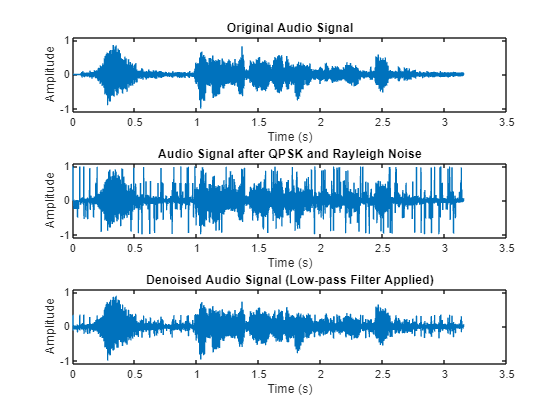

sound(audioFiltered, fs);
pause(length(audioFiltered)/fs + 1);

%% Plot the Signals for Comparison
t = (0:length(audioIn)-1) / fs;  % Time vector

figure;
subplot(3,1,1);
plot(t, audioIn);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.1 1.1]);

subplot(3,1,2);
plot(t, audioNoisy);
title('Audio Signal after QPSK and Rayleigh Noise');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.1 1.1]);

subplot(3,1,3);
plot(t, audioFiltered);
title('Denoised Audio Signal (Low-pass Filter Applied)');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.1 1.1]);


%% Save the Processed Audio Files
audiowrite('noisy_audio.wav', audioNoisy, fs);
audiowrite('denoised_audio.wav', audioFiltered, fs);

%% Debug Information
fprintf('Original signal length: %d\n', length(audioIn));

Original signal length: 151200


fprintf('Noisy signal length: %d\n', length(audioNoisy));

Noisy signal length: 151200


fprintf('Filtered signal length: %d\n', length(audioFiltered));

Filtered signal length: 151200


fprintf('SNR (dB): %.2f\n', desiredSNR_dB);

SNR (dB): 10.00


fprintf('Noise scale: %.2f\n', noiseScale);

Noise scale: 0.40



disp('Audio processing complete. Files saved.');

Audio processing complete. Files saved.
